app = winAppAnalise;

% Abre-se, por meio da GUI, o arquivo indicado a seguir, marcando como
% emissão o sinal centralizado em 101.540 MHz, com largura igual a 150 kHz.

Fonte da informação: **appColeta_250404_T161909_ID1_1.bin**

A seguir a emissão sob análise. A largura de banda foi escolhida para que fique 30dB acima do piso de ruído.

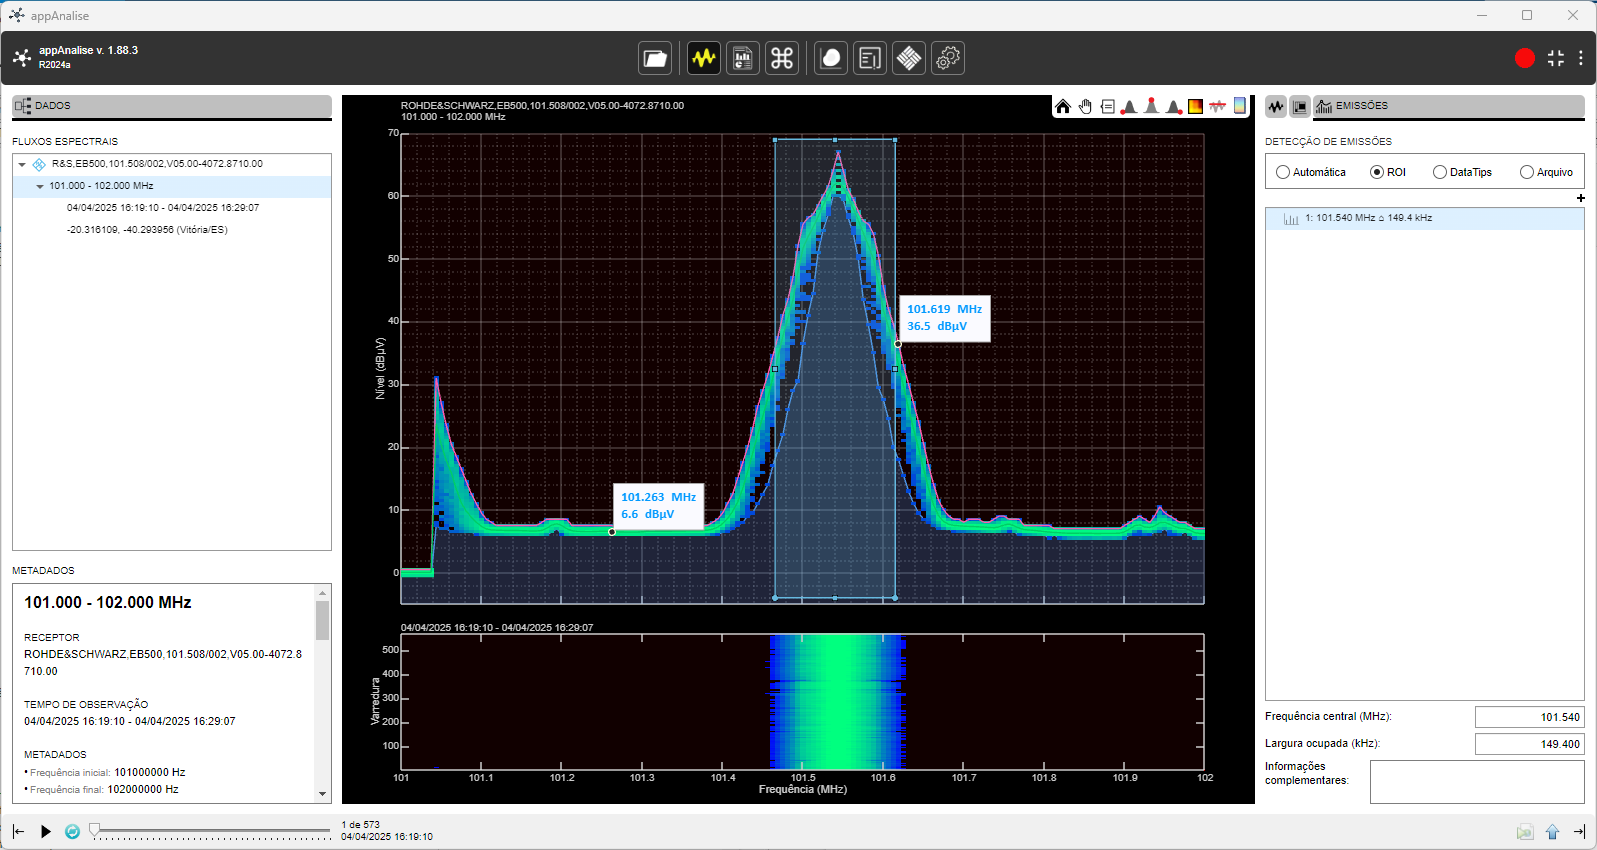

A seguir o local de instalação da emissora, além do ponto da monitoração. O azimute de TX-RF é 100.1º (NV). Logo, o azimute RX-TX é **280.1º (NV)**.

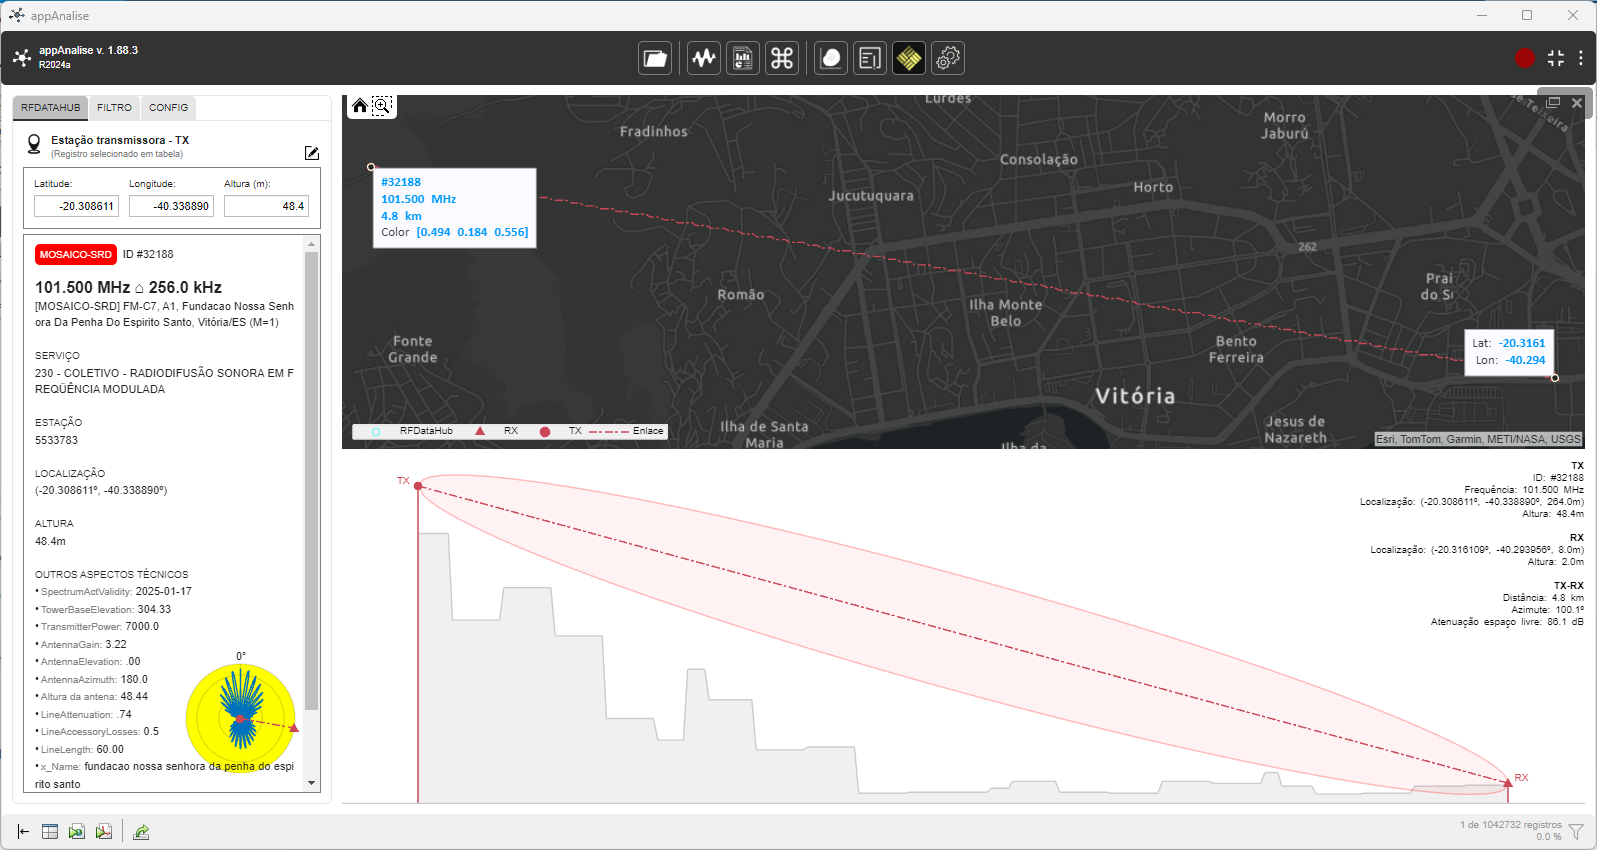

Declinação magnética:

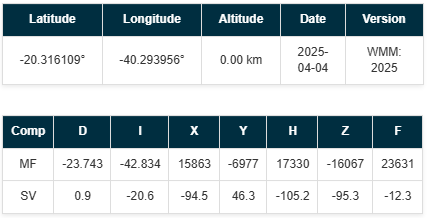

emissionFreq = app.specData.UserData.Emissions.Frequency(1) * 1e+6 % MHz >> Hertz

emissionFreq = 1.0154e+08

emissionBW   = app.specData.UserData.Emissions.BW_kHz(1)    * 1000 % kHz >> Hertz

emissionBW = 1.4812e+05


idx1 = freq2idx(app.bandObj, emissionFreq - emissionBW/2)

idx1 = 76

idx2 = freq2idx(app.bandObj, emissionFreq + emissionBW/2)

idx2 = 100

% Em relação ao NM:
azimuthMatrix  = app.specData.Data{4}(idx1:idx2, :)

azimuthMatrix = 25×573 single matrix
  308.8000  135.4000  114.0000  299.2000  126.0000  122.2000  320.2000  119.7000  129.4000   12.7000  155.5000  166.5000  131.5000  133.7000  112.5000  110.8000  154.3000  141.5000  142.1000  120.8000  137.8000  137.2000   98.2000  187.8000  119.7000  128.8000  327.6700  134.7000   56.9000  133.8000   16.2000  129.8000  136.9000  135.9000  162.2000  135.9000  151.2000  123.1000  102.2000  139.8000  161.7000  116.9000  144.6000  158.4000  198.9000  135.6000  110.1000  154.1000  153.0000   53.6000
  309.0000  310.1000  114.8000  310.7000  137.8000  119.2000  310.1000  120.6000  130.7000  167.2000  144.9000  159.6000  125.2000  131.7000  127.3000  133.2000  148.4000  134.2000  140.4000  118.1000  148.8000  125.1000  122.1000  174.4000  116.9000  122.6000  159.3000  133.7000   33.4000  139.7000    5.1000  131.6000  162.1000  130.3000  153.7000  136.8000  149.4000  110.4000  115.7000  295.7000  327.6700  107.6000  133.5000  136.4000  145.4000  123.5000  

qualityNote  = double(app.specData.Data{5}(idx1:idx2, :) > 85);
qualityNote(~qualityNote) = NaN

qualityNote =    NaN     1   NaN   NaN     1   NaN   NaN     1   NaN   NaN     1   NaN   NaN   NaN   NaN   NaN     1   NaN     1     1   NaN     1   NaN     1     1     1   NaN   NaN   NaN   NaN   NaN   NaN     1   NaN   NaN   NaN   NaN   NaN     1   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     1   NaN   NaN
     1   NaN   NaN     1   NaN   NaN     1     1   NaN   NaN     1     1     1     1   NaN   NaN   NaN   NaN   NaN     1   NaN     1   NaN     1     1   NaN     1   NaN   NaN     1   NaN     1   NaN   NaN   NaN     1   NaN   NaN     1   NaN   NaN     1   NaN   NaN   NaN   NaN   NaN     1   NaN   NaN
     1     1   NaN     1   NaN   NaN     1     1     1   NaN   NaN   NaN   NaN     1   NaN     1   NaN   NaN     1     1   NaN     1   NaN     1     1   NaN   NaN   NaN   NaN     1   NaN     1   NaN   NaN   NaN     1     1   NaN   NaN     1     1     1     1   NaN   NaN   NaN   NaN   NaN     1   NaN
     1     1   NaN     1   NaN     1     1     1     1   NaN   NaN   NaN   NaN   Na

azimuthMatrix .* qualityNote

ans = 25×573 single matrix
       NaN  135.4000       NaN       NaN  126.0000       NaN       NaN  119.7000       NaN       NaN  155.5000       NaN       NaN       NaN       NaN       NaN  154.3000       NaN  142.1000  120.8000       NaN  137.2000       NaN  187.8000  119.7000  128.8000       NaN       NaN       NaN       NaN       NaN       NaN  136.9000       NaN       NaN       NaN       NaN       NaN  102.2000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  154.1000       NaN       NaN
  309.0000       NaN       NaN  310.7000       NaN       NaN  310.1000  120.6000       NaN       NaN  144.9000  159.6000  125.2000  131.7000       NaN       NaN       NaN       NaN       NaN  118.1000       NaN  125.1000       NaN  174.4000  116.9000       NaN  159.3000       NaN       NaN  139.7000       NaN  131.6000       NaN       NaN       NaN  136.8000       NaN       NaN  115.7000       NaN       NaN  107.6000       NaN       NaN       NaN       NaN       NaN  

azimuth_85_mean_NM   = mean(azimuthMatrix .* qualityNote, "omitmissing")

azimuth_85_mean_NM = 1×573 single row vector
  244.0900  229.3750  219.1875  209.8938  141.6208  151.7867  235.6188  180.1000  157.1058  202.2671  195.3636  210.7100  177.9444  208.6000  293.8000  148.8500  176.2143  153.7857  170.0600  147.9538  176.6143  175.9636  183.7556  146.7417  153.8357  150.7364  183.2744  215.6727  175.7428  170.0833  188.3786  157.0000  130.8333  194.3143  175.2750  131.4250  141.1583  196.3750  136.3615  120.8800  223.0800  139.9143  161.1400  205.3600  219.1571  287.8000  145.5500  143.4364  185.4625  186.7088


azimuth_85_median_NM = median(azimuthMatrix .* qualityNote, "omitmissing")

azimuth_85_median_NM = 1×573 single row vector
  309.1000  299.6000  271.5000  213.7000  132.2000  132.8000  284.5500  126.8500  130.2500  144.1000  155.5000  211.3500  129.2000  148.1000  299.4000  131.9000  140.6000  133.5000  138.3000  128.9000  133.4000  134.0000  134.1000  130.4500  126.7500  128.7000  135.1000  282.5000  134.1000  137.4500  148.7000  131.6000  134.2000  137.5000  136.0500  135.9000  128.0500  200.8500  115.7000  122.6000  275.7500  115.9000  135.4000  207.8000  291.1000  286.3000  133.4500  131.1000  138.0500  128.6000



% Em relação ao NV:
magDeclination = -23.743;
azimuth_85_mean_NV   = azimuth_85_mean_NM   + magDeclination

azimuth_85_mean_NV = 1×573 single row vector
  220.3470  205.6320  195.4445  186.1508  117.8778  128.0437  211.8758  156.3570  133.3628  178.5241  171.6206  186.9670  154.2014  184.8570  270.0570  125.1070  152.4713  130.0427  146.3170  124.2108  152.8713  152.2206  160.0126  122.9987  130.0927  126.9934  159.5314  191.9297  151.9998  146.3403  164.6356  133.2570  107.0903  170.5713  151.5320  107.6820  117.4153  172.6320  112.6185   97.1370  199.3370  116.1713  137.3970  181.6170  195.4141  264.0570  121.8070  119.6934  161.7195  162.9658


azimuth_85_median_NV = azimuth_85_median_NM + magDeclination

azimuth_85_median_NV = 1×573 single row vector
  285.3570  275.8570  247.7570  189.9570  108.4570  109.0570  260.8070  103.1070  106.5070  120.3570  131.7570  187.6070  105.4570  124.3570  275.6570  108.1570  116.8570  109.7570  114.5570  105.1570  109.6570  110.2570  110.3570  106.7070  103.0070  104.9570  111.3570  258.7570  110.3570  113.7070  124.9570  107.8570  110.4570  113.7570  112.3070  112.1570  104.3070  177.1070   91.9570   98.8570  252.0070   92.1570  111.6570  184.0570  267.3570  262.5570  109.7070  107.3570  114.3070  104.8570


Tela do EB500GUI registrada no momento da coleta.

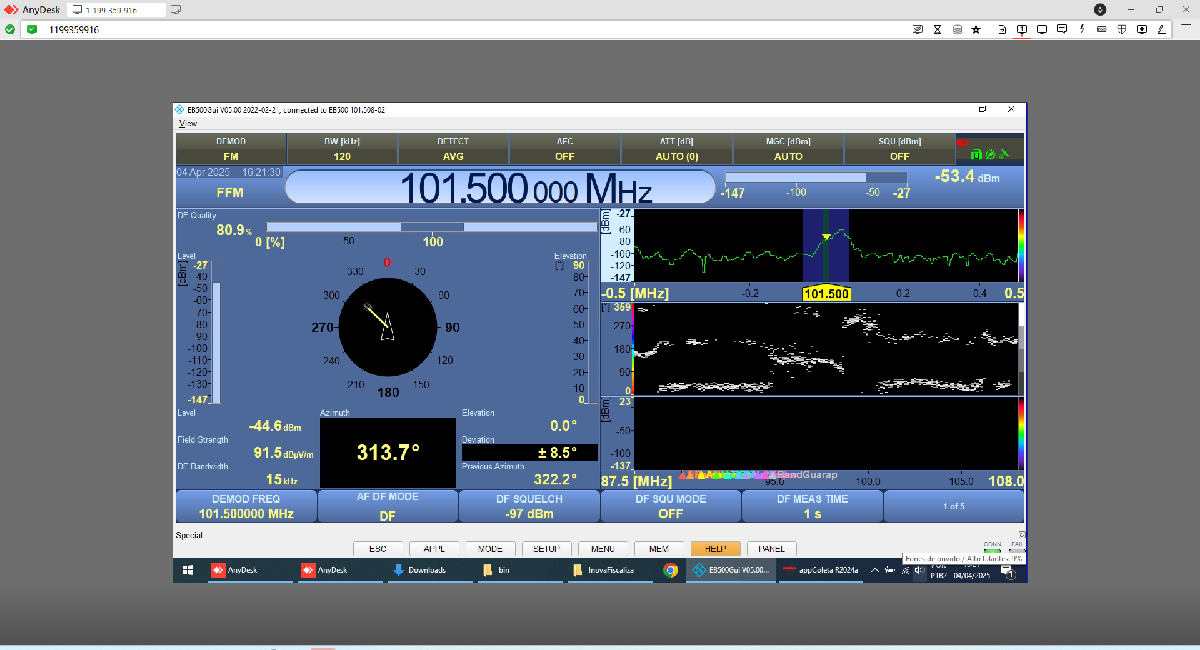

Em detalhe o plot de azimute por ponto de medição do EB500GUI seguido dos dados coletados pelo appColeta:

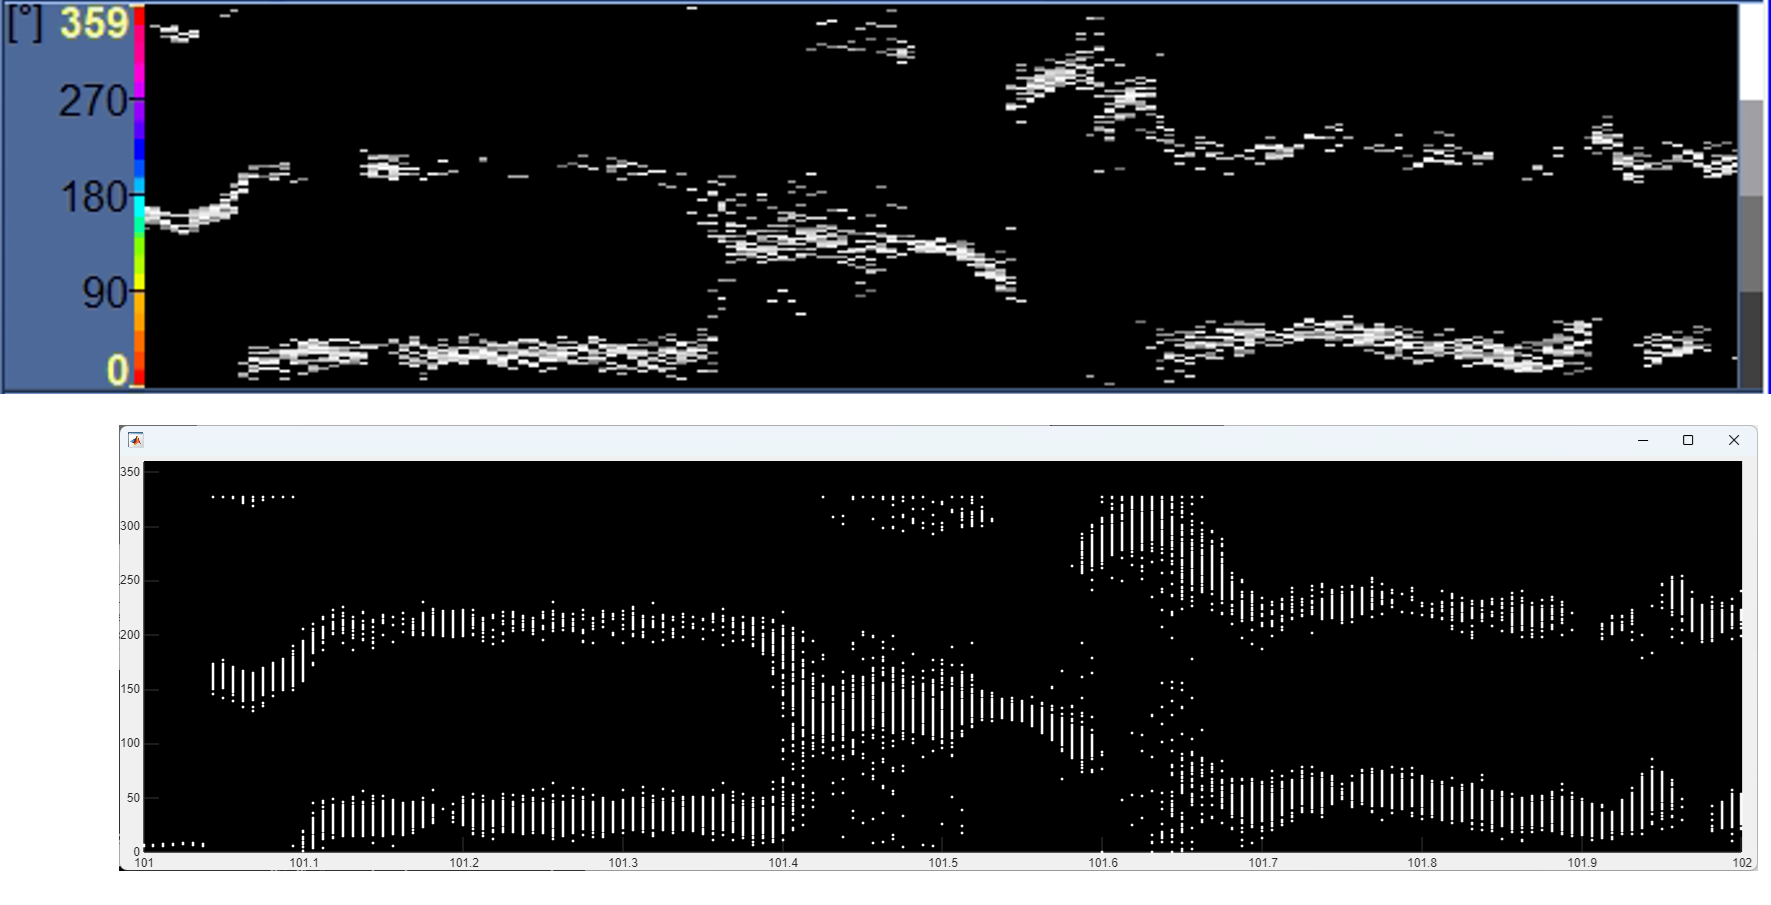

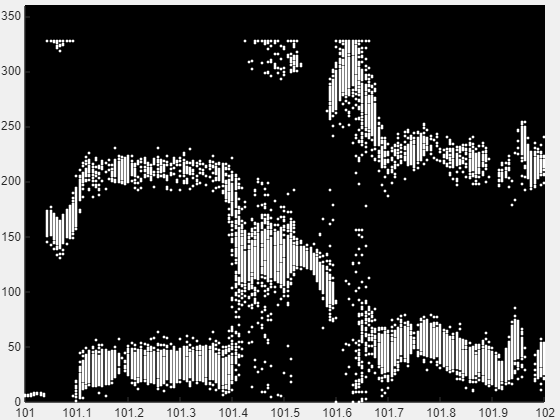

xArray = linspace(app.specData.MetaData.FreqStart/1e+6, app.specData.MetaData.FreqStop/1e+6, app.specData.MetaData.DataPoints);
fig = uifigure;
ax = uiaxes(fig, 'Units', 'normalized', 'Position', [0,0,1,1], 'Color', 'black', 'YLim', [0,360]);
plot(ax, xArray, app.specData.Data{4}(:, 1:100)', 'LineStyle', 'none', 'Marker', '.', 'Color', 'white')